location = 'D:\Elastic2D_Propagation\dataVoidDetection\data 200x200' 

location = 'D:\Elastic2D_Propagation\dataVoidDetection\data 200x200'

Imds = imageDatastore(location,'IncludeSubFolders',true,'FileExtensions','.png','LabelSource','foldernames');

Randomly select and plot 20 images from the dataset

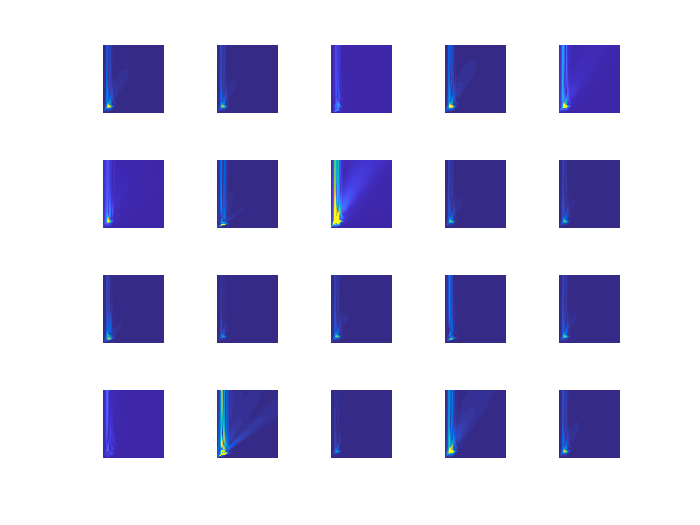

numImages = 285;
perm = randperm(numImages,20);
for np = 1:20
    subplot(4,5,np)
    im = imread(Imds.Files{perm(np)});
    imagesc(im);
    colormap gray; axis off;
end

# Wavelet Image Scattering Feature Extraction

sf = waveletScattering2('ImageSize',[200 200],'InvarianceScale',100, ...
    'NumRotations',[8 8]);

if isempty(gcp)
    parpool;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).


Test and Train set 

rng(10); % Set random seed for reproducibility
Imds = shuffle(Imds); % Shuffle the dataset

% Split into train, validation, and test sets
[trainImds, testImds] = splitEachLabel(Imds, 0.7);  % 50% for training
% [validImds, testImds] = splitEachLabel(remainingImds, 0.6); % 60% of remaining for validation, 40% for testing

Ttrain = tall(trainImds);
% Tvalid = tall(validImds);
Ttest = tall(testImds);

% Extract features for each set
trainfeatures = cellfun(@(x)helperScatImages(sf,x), Ttrain, 'UniformOutput', false);
% validfeatures = cellfun(@(x)helperScatImages(sf,x), Tvalid, 'UniformOutput', false);
testfeatures = cellfun(@(x)helperScatImages(sf,x), Ttest, 'UniformOutput', false);

Use `tall`'s `gather` capability to concatenate all the training and test features.

Trainf = gather(trainfeatures);

Evaluating tall expression using the Parallel Pool 'Processes':
- Pass 1 of 1: Completed in 4 min 46 sec
Evaluation completed in 4 min 46 sec


trainfeatures = cat(2,Trainf{:});
Testf = gather(testfeatures);

Evaluating tall expression using the Parallel Pool 'Processes':
- Pass 1 of 1: Completed in 2 min 4 sec
Evaluation completed in 2 min 4 sec


testfeatures = cat(2,Testf{:});

% Validf = gather(validfeatures);
% validfeatures = cat(2,Validf{:});

# **PCA Model and Prediction**

% model = helperPCAModel(trainfeatures,30,trainImds.Labels);
% predlabels = helperPCAClassifier(testfeatures,model);

After constructing the model and classifying the test set, determine the accuracy of the test set classification.

% % Calculate accuracy
% accuracy = sum(testImds.Labels == predlabels) / numel(testImds.Labels) * 100;
% fprintf('Accuracy: %.2f%%\n', accuracy);
% % % Calculate precision and recall
% % % [precision, recall] = perfcurve(predlabels, score(:, 2), 'LowFlow', 'XCrit', 'prec', 'YCrit', 'reca');
% % 
% % % Display precision and recall values
% % fprintf('Precision: %.2f\n', precision);
% % fprintf('Recall: %.2f\n', recall);

% figure;
% confusionchart(testImds.Labels,predlabels)
% title('Test-Set Confusion Matrix -- Wavelet Scattering')

# **CNN**

imageSize = [200 200 3];
% Layer 1: Convolutional block

layer1 = [
    convolution2dLayer(3, 16)
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
];


% Layer 2: Convolutional block
layer2 = [
    convolution2dLayer(3, 32)
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
];

% Layer 2: Convolutional block
layer3 = [
    convolution2dLayer(3, 16)
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
];

% Layer 3: Fully connected block
layer4 = [
    fullyConnectedLayer(200)
    reluLayer
    fullyConnectedLayer(2)
    softmaxLayer
];

layers = [
    imageInputLayer(imageSize)
    layer1
    layer2
    layer3
    flattenLayer
    layer4
    classificationLayer
];

Use stochastic gradient descent with momentum and a learning rate of 0.0001 for training. Set the maximum number of epochs to 20. For reproducibility, set the `ExecutionEnvironment` to `'cpu'`.

options = trainingOptions('sgdm', ...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4, ...
    'MiniBatchSize', 20, ...
    'Verbose',false, ...
    'Plots','training-progress','ExecutionEnvironment','gpu');

Train the network. For training and testing we use the same data sets used in the scattering transform.

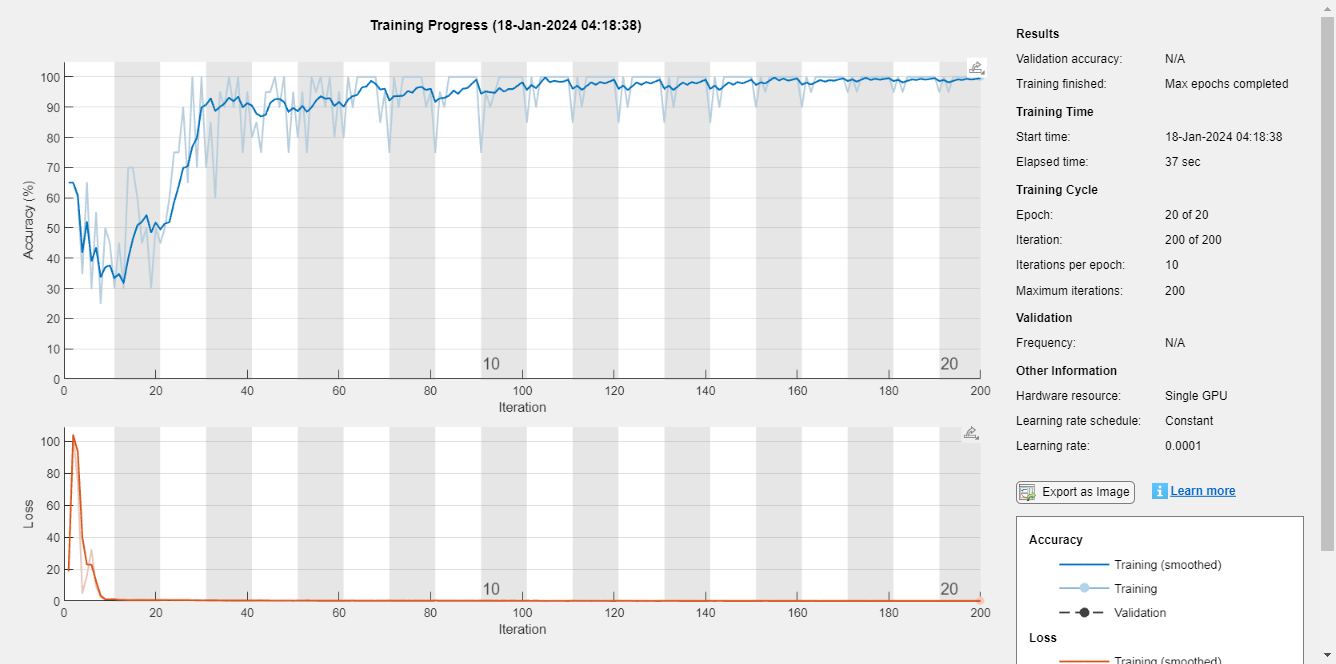

reset(trainImds);
reset(testImds);
net = trainNetwork(trainImds, layers, options);

Save the model

# Evaluate Result

YPred = classify(net,testImds,'ExecutionEnvironment','cpu');
DCNNaccuracy = sum(YPred == testImds.Labels)/numel(YPred)*100

DCNNaccuracy = 97.6471

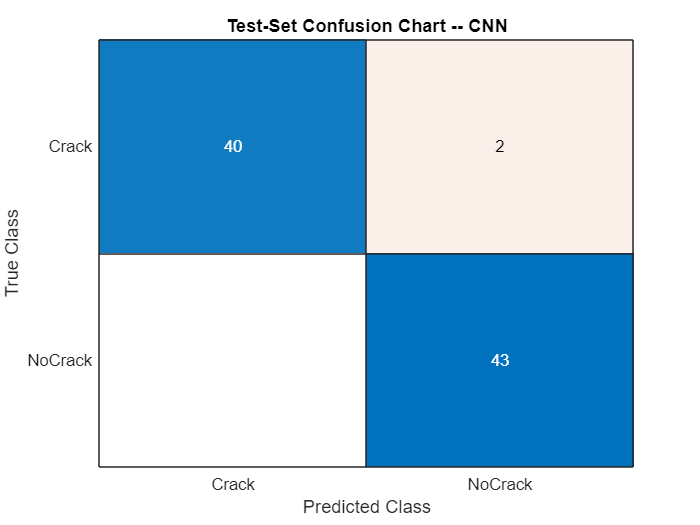

figure;
confusionchart(testImds.Labels,YPred)
title('Test-Set Confusion Chart -- CNN')

% % Export the trained network to ONNX format
% tfFileName = 'D:\Elastic2D_Propagation\Wavelet Scattering report\cnn_waveletscattering.onnx';
% exportNetworkToTensorFlow(net, tfFileName);

# **Appendix — Supporting Functions**

**helpScatImages**

function features = helperScatImages(sf,x)
% This function is only to support examples in the Wavelet Toolbox.
% It may change or be removed in a future release.

% Copyright 2018 MathWorks

smat = featureMatrix(sf,x,'transform','log');
features = mean(mean(smat,2),3);
end

**helperPCAModel**

function model = helperPCAModel(features,M,Labels)
% This function is only to support wavelet image scattering examples in 
% Wavelet Toolbox. It may change or be removed in a future release.
% model = helperPCAModel(features,M,Labels)

% Copyright 2018 MathWorks

% Initialize structure array to hold the affine model
model = struct('Dim',[],'mu',[],'U',[],'Labels',categorical([]),'s',[]);
model.Dim = M;
% Obtain the number of classes
LabelCategories = categories(Labels);
Nclasses = numel(categories(Labels));
for kk = 1:Nclasses
    Class = LabelCategories{kk};
    % Find indices corresponding to each class
    idxClass = Labels == Class;
    % Extract feature vectors for each class
    tmpFeatures = features(:,idxClass);
    % Determine the mean for each class
    model.mu{kk} = mean(tmpFeatures,2);
    [model.U{kk},model.S{kk}] = scatPCA(tmpFeatures);
    if size(model.U{kk},2) > M
        model.U{kk} = model.U{kk}(:,1:M);
        model.S{kk} = model.S{kk}(1:M);
        
    end
    model.Labels(kk) = Class;
end
    
function [u,s,v] = scatPCA(x,M)
	% Calculate the principal components of x along the second dimension.

	if nargin > 1 && M > 0
		% If M is non-zero, calculate the first M principal components.
	    [u,s,v] = svds(x-sig_mean(x),M);
	    s = abs(diag(s)/sqrt(size(x,2)-1)).^2;
	else
		% Otherwise, calculate all the principal components.
        % Each row is an observation, i.e. the number of scattering paths
        % Each column is a class observation
		[u,d] = eig(cov(x'));
		[s,ind] = sort(diag(d),'descend');
		u = u(:,ind);
	end
end
end

**helperPCAClassifier**

function labels = helperPCAClassifier(features,model)
% This function is only to support wavelet image scattering examples in 
% Wavelet Toolbox. It may change or be removed in a future release.
% model is a structure array with fields, M, mu, v, and Labels
% features is the matrix of test data which is Ns-by-L, Ns is the number of
% scattering paths and L is the number of test examples. Each column of
% features is a test example.

% Copyright 2018 MathWorks

labelIdx = determineClass(features,model); 
labels = model.Labels(labelIdx); 
% Returns as column vector to agree with imageDatastore Labels
labels = labels(:);


%--------------------------------------------------------------------------
function labelIdx = determineClass(features,model)
% Determine number of classes
Nclasses = numel(model.Labels);
% Initialize error matrix
errMatrix = Inf(Nclasses,size(features,2));
for nc = 1:Nclasses
    % class centroid
    mu = model.mu{nc};
    u = model.U{nc};
    % 1-by-L
    errMatrix(nc,:) = projectionError(features,mu,u);
end
% Determine minimum along class dimension
[~,labelIdx] = min(errMatrix,[],1);   


%--------------------------------------------------------------------------
function totalerr = projectionError(features,mu,u)
    %
    Npc = size(u,2);
    L = size(features,2);
    % Subtract class mean: Ns-by-L minus Ns-by-1
    s = features-mu;
    % 1-by-L
    normSqX = sum(abs(s).^2,1)';
    err = Inf(Npc+1,L);
	err(1,:) = normSqX;
    err(2:end,:) = -abs(u'*s).^2;
    % 1-by-L
    totalerr = sqrt(sum(err,1));
end
end
end